clear all; clc;

% No correction no LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/zurich/mabs_i1_c0_l0.mat')
dphase_1_0_0.lls = error_lls;
dphase_1_0_0.nlls = error_nlls;
[dphase_1_0_0.F_lls, dphase_1_0_0.X_lls] = ecdf(error_lls);
[dphase_1_0_0.F_nlls, dphase_1_0_0.X_nlls] = ecdf(error_nlls);

% Correction no LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/zurich/mabs_i1_c1_l0.mat')
dphase_1_1_0.lls = error_lls;
dphase_1_1_0.nlls = error_nlls;
[dphase_1_1_0.F_lls, dphase_1_1_0.X_lls] = ecdf(error_lls);
[dphase_1_1_0.F_nlls, dphase_1_1_0.X_nlls] = ecdf(error_nlls);

% Correction with LTE
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/zurich/mabs_i1_c1_l1.mat')
dphase_1_1_1.lls = error_lls;
dphase_1_1_1.nlls = error_nlls;
[dphase_1_1_1.F_lls, dphase_1_1_1.X_lls] = ecdf(error_lls);
[dphase_1_1_1.F_nlls, dphase_1_1_1.X_nlls] = ecdf(error_nlls);

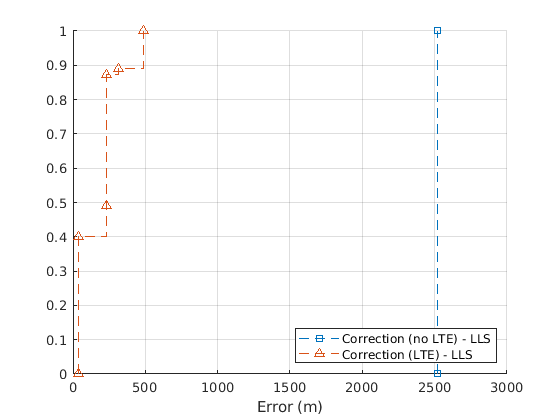

% Plotting
figure(); hold on; grid on;
% stairs(dphase_1_0_0.X_lls, dphase_1_0_0.F_lls, '--');
% stairs(dphase_1_0_0.X_nlls, dphase_1_0_0.F_nlls, ':');
stairs(dphase_1_1_0.X_lls, dphase_1_1_0.F_lls, '--s');
% stairs(dphase_1_1_0.X_nlls, dphase_1_1_0.F_nlls, ':s');
stairs(dphase_1_1_1.X_lls, dphase_1_1_1.F_lls, '--^');
% stairs(dphase_1_1_1.X_nlls, dphase_1_1_1.F_nlls, ':^');
legend( 'Correction (no LTE) - LLS', 'Correction (LTE) - LLS','Location','southeast');
xlabel('Error (m)');